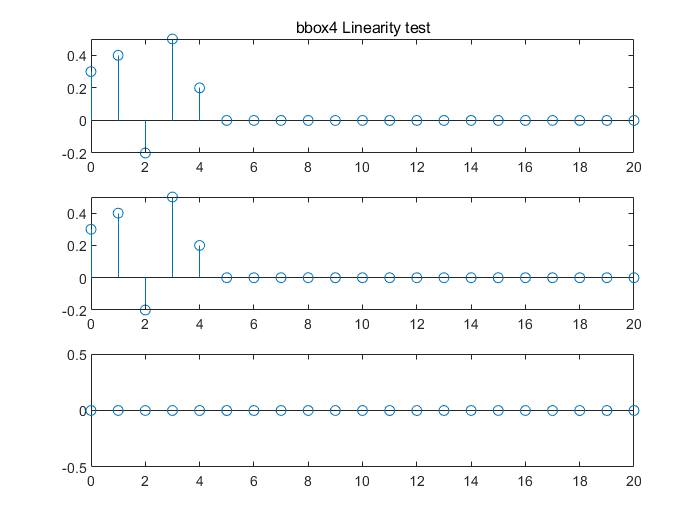


clc;
clear;
close all;

n1=-5:20;
delta_n=(n1==0);
delta_n1=(n1==1);

% linearity
figureName = 'bbox4 Linearity test';
figure('Name', figureName);
subplot(3,1,1)
stem(n1,bbox4(2*delta_n1      +delta_n)), title('bbox4 Linearity test'), xlim([0,20])
subplot(3,1,2)
stem(n1,bbox4(delta_n)+2*bbox4(delta_n1))
xlim([0,20])
subplot(3,1,3)
stem(n1,bbox4(delta_n)+2*bbox4(delta_n1)-bbox4(2*delta_n1 +delta_n))
ylim([-0.5,0.5])
xlim([0,20])

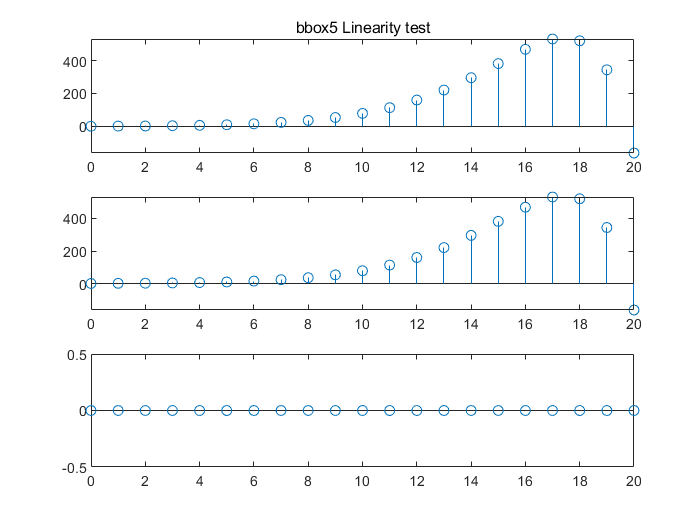


figureName = 'bbox5 Linearity test';  
figure('Name', figureName);  
subplot(3,1,1)
stem(n1,bbox5(delta_n)+2*bbox5(delta_n1)),title('bbox5 Linearity test') 
xlim([0,20])
subplot(3,1,2)
stem(n1,bbox5(2*delta_n1+delta_n))
xlim([0,20])
subplot(3,1,3)
stem(n1,bbox5(delta_n)+2*bbox5(delta_n1)-bbox5(2*delta_n1+delta_n))
ylim([-0.5,0.5])
xlim([0,20])

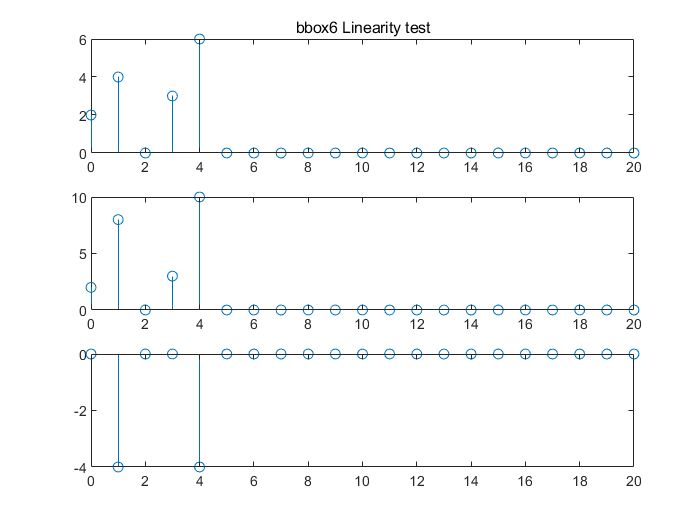


figureName = 'bbox6 Linearity test';  
figure('Name', figureName);  
subplot(3,1,1)
stem(n1,bbox6(delta_n)+2*bbox6(delta_n1)),title('bbox6 Linearity test') 
xlim([0,20])
subplot(3,1,2)
stem(n1,bbox6(2*delta_n1+delta_n))
xlim([0,20])
subplot(3,1,3)
stem(n1,bbox6(delta_n)+2*bbox6(delta_n1)-bbox6(2*delta_n1+delta_n))
xlim([0,20])

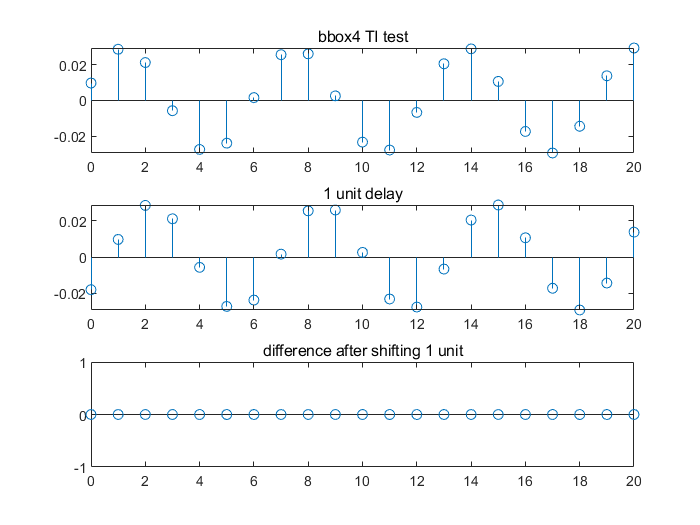



%  Time Invariant

n2=-5:21;
delta_n=cos(n2);
delta_n1=cos(n2-1);

figureName = 'bbox4 TI test';  
figure('Name', figureName);  
subplot(3,1,1)
stem(n2,bbox4(delta_n)),title('bbox4 TI test') 
xlim([0,20])
subplot(3,1,2)
y4=bbox4(delta_n1);
x4=y4(2:length(y4));
y41=[x4,0];
stem(n2,bbox4(delta_n1)),title('1 unit delay') 
xlim([0,20])
subplot(3,1,3)
stem(n2,y41-bbox4(delta_n)),title('difference after shifting 1 unit') 
xlim([0,20])

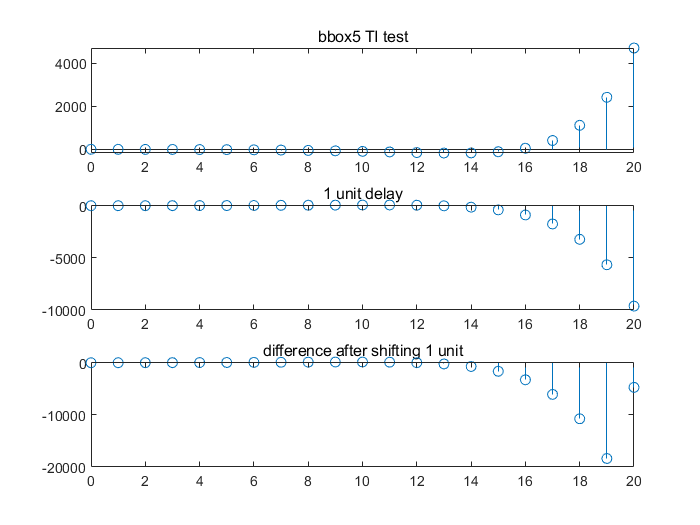



figureName = 'bbox5 TI test';  
figure('Name', figureName);  
subplot(3,1,1)
stem(n2,bbox5(delta_n)),title('bbox5 TI test') 
xlim([0,20])
subplot(3,1,2)
y5=bbox5(delta_n1);
x5=y5(3:length(y5));
y51=[x5,0,0];
stem(n2,bbox5(delta_n1)),title('1 unit delay') 
xlim([0,20])
subplot(3,1,3)
stem(n2,y51-bbox5(delta_n)),title('difference after shifting 1 unit') 
xlim([0,20])

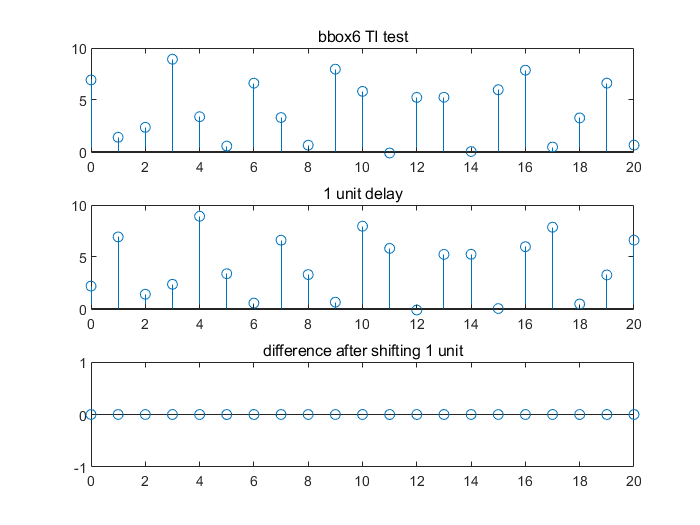


figureName = 'bbox6 TI test';  
figure('Name', figureName);  
subplot(3,1,1)
stem(n2,bbox6(delta_n)),title('bbox6 TI test') 
xlim([0,20])
subplot(3,1,2)
y6=bbox6(delta_n1);
x6=y6(2:length(y6));
y61=[x6,0];
stem(n2,bbox6(delta_n1)),title('1 unit delay') 
xlim([0,20])
subplot(3,1,3)
stem(n2,y61-bbox6(delta_n)),title('difference after shifting 1 unit') 
xlim([0,20])